load('glass_prop.mat')
load('small_set.mat')

%declaration of global variables
global beaker_volume beakerinnerdim beakerouterdim beakerheight mantel_A;
global top_A Tinf humidity k_glass rho_glass cp_glass epsilon_glass L_glass kc_coeff;
global heatcontribution_top heatcontribution_mantel y0 h_mantel_coeff

beaker_volume = glass.beaker_size(1); %m3
beakerinnerdim = glass.inner_diameter(1); %m
beakerouterdim = glass.outer_diameter(1); %m
beakerheight = glass.height(1); %m
[mantel_A, top_A] = coffeCupArea(beakerouterdim,beakerinnerdim);
Tinf = 20.6+273; %room temprature
humidity = 0.22; %room humidity
k_glass = glass.heat_conduction;
rho_glass = glass.density;
cp_glass = glass.heat_capacity;
epsilon_glass = glass.emissioncoeff;
L_glass = 1.5e-3;
heatcontribution_top = [];
heatcontribution_mantel = [];

% Initial values for temperature and mass
y0 = [(273.15+80),0.126];

% Time interval where the ODE is solved
tint = linspace(0,37.5,76).*60; %[1 2250];


kc_coeff = 1;
h_mantel_coeff =1;
heatcontribution_top = [];
heatcontribution_mantel = [];
[t,Y]  = ode45(@(t,Y)sysdiff(t,Y),tint,y0);

R2_model = [0;0;0];
for c1 = linspace(1,3,20) 
    for c2 = linspace(0,1,20)
        h_mantel_coeff = c1;
        kc_coeff = c2;
        
        % ODE solver
        [t,Y]  = ode45(@(t,Y)sysdiff(t,Y),tint,y0);
        
        SSres_temp = sum((small(2).beaker(:,2)+273.15-Y(:,1)).^2);
        SStot_temp = sum((small(2).beaker(:,2)+273.15-mean(small(2).beaker(:,2)+273.15)).^2);
        R2_temp = 1 - (SSres_temp/SStot_temp);
        
        SSres_mass = sum((small(2).beaker(:,3)-Y(:,2)*1000).^2);
        SStot_mass = sum((small(2).beaker(:,3)-mean(small(2).beaker(:,3))).^2);
        R2_mass = 1 - (SSres_mass/SStot_mass);
        
        R2_model = [R2_model ,[(R2_temp+R2_mass)/2;c1;c2]];
        
    end
end

[R2,i] = max(R2_model(1,:))
best_coeff = [R2_model(2,i),R2_model(3,i)]

heatcontribution_top = [];
heatcontribution_mantel = [];
h_mantel_coeff = best_coeff(1)
kc_coeff = best_coeff(2)

[t,Y]  = ode45(@(t,Y)sysdiff(t,Y),tint,y0);

%best coeff [1.736842105263158,0.684210526315790]

h_mantel_coeff = 1.736842105263158

h_mantel_coeff = 1.7368

kc_coeff = 0.684210526315790

kc_coeff = 0.6842


[t,Y]  = ode45(@(t,Y)sysdiff(t,Y),tint,y0);

%best coeff [1.736842105263158,0.684210526315790]

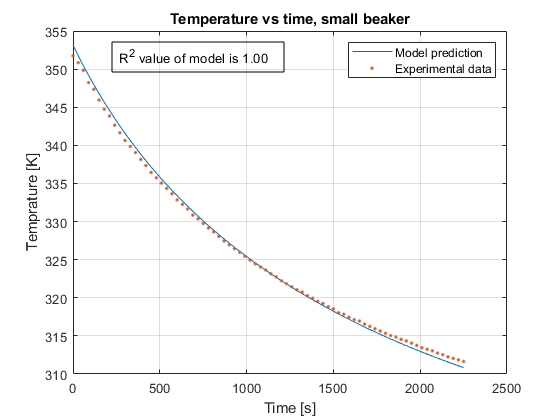

%Plotting experimental data vs modell for temperature
SSres_temp = sum((small(2).beaker(:,2)+273.15-Y(:,1)).^2);
SStot_temp = sum((small(2).beaker(:,2)+273.15-mean(small(2).beaker(:,2)+273.15)).^2);
R2 = 1 - (SSres_temp/SStot_temp);
R2string = sprintf('R^2 value of model is %.2f ',R2);

plot(t,Y(:,1),small(2).beaker(:,1)*60,small(2).beaker(:,2)+273.15,'.')

dim = [.2 .6 .3 .3];
annotation('textbox',dim,'String',R2string,'FitBoxToText','on');

title('Temperature vs time, small beaker')
legend('Model prediction','Experimental data')
xlabel('Time [s]')
ylabel('Temprature [K]')
grid on

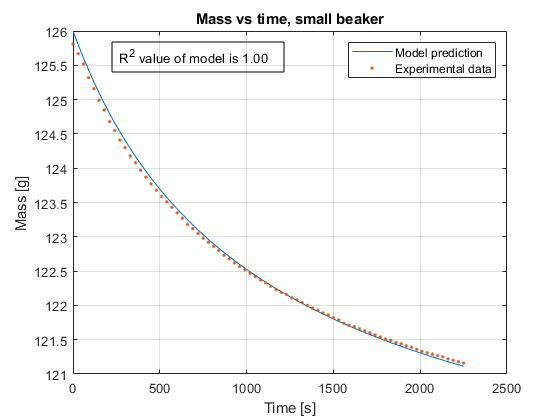

%Plotting experimental data vs modell for mass
SSres_mass = sum((small(2).beaker(:,3)-Y(:,2)*1000).^2);
SStot_mass = sum((small(2).beaker(:,3)-mean(small(2).beaker(:,3))).^2);
R2 = 1 - (SSres_mass/SStot_mass);

R2string = sprintf('R^2 value of model is %.2f ',R2);


plot(t,Y(:,2)*1000,small(2).beaker(:,1)*60,small(2).beaker(:,3),'.')

dim = [.2 .6 .3 .3];
annotation('textbox',dim,'String',R2string,'FitBoxToText','on');

title('Mass vs time, small beaker')
legend('Model prediction','Experimental data')
xlabel('Time [s]')
ylabel('Mass [g]')
grid on

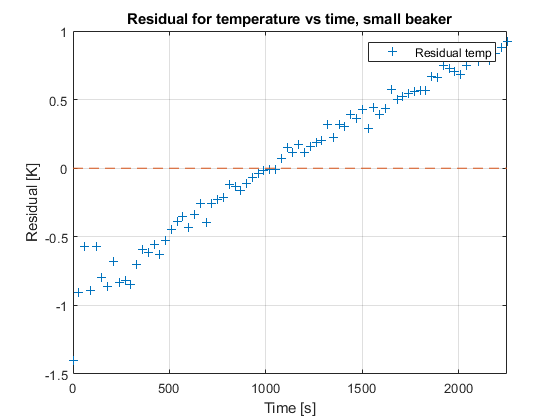

%plots residual temperature
residual_temp = (small(2).beaker(:,2)+273.15) - Y(:,1);

plot(t,residual_temp,'+',[t(1) t(end)],[0 0],'--')
%plot([t(1) t(end)],[0 0],'--')


title('Residual for temperature vs time, small beaker')
legend('Residual temp')
xlabel('Time [s]')
ylabel('Residual [K]')
xlim([t(1) t(end)])
grid on

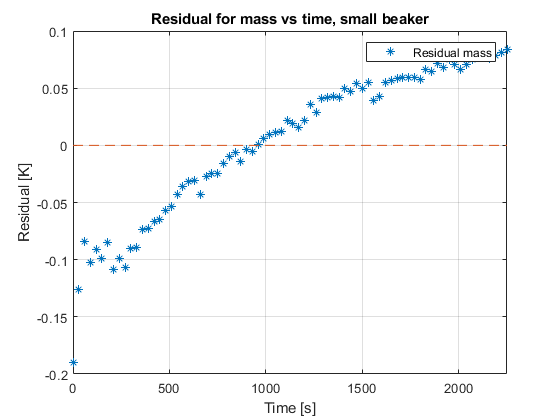

%plots residual mass
residual_mass = small(2).beaker(:,3) - Y(:,2)*1000;

plot(t,residual_mass,'*',[t(1) t(end)],[0 0],'--')
%plot([t(1) t(end)],[0 0],'--')


title('Residual for mass vs time, small beaker')
legend('Residual mass')
xlabel('Time [s]')
ylabel('Residual [K]')
xlim([t(1) t(end)])
grid on

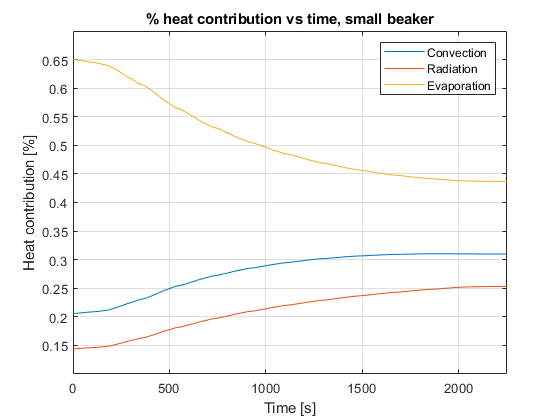

%heat contribution plot
sumheatcontribution = heatcontribution_top(:,1)+heatcontribution_top(:,2)+heatcontribution_top(:,3)+heatcontribution_mantel(:,1)+heatcontribution_mantel(:,2);

heatcontribution_convection = (heatcontribution_top(:,1) + heatcontribution_mantel(:,1))./sumheatcontribution;
heatcontribution_radiation = (heatcontribution_top(:,2) + heatcontribution_mantel(:,2))./sumheatcontribution;
heatcontribution_evaporation = heatcontribution_top(:,3)./sumheatcontribution;

t_heat = linspace(0,37.5,length(sumheatcontribution)).*60;
plot(t_heat,smooth(heatcontribution_convection),t_heat,smooth(heatcontribution_radiation),t_heat,smooth(heatcontribution_evaporation))

title('% heat contribution vs time, small beaker')
legend('Convection', 'Radiation', 'Evaporation')
xlabel('Time [s]')
ylabel('Heat contribution [%]')
xlim([t_heat(1) t_heat(end)])
grid on

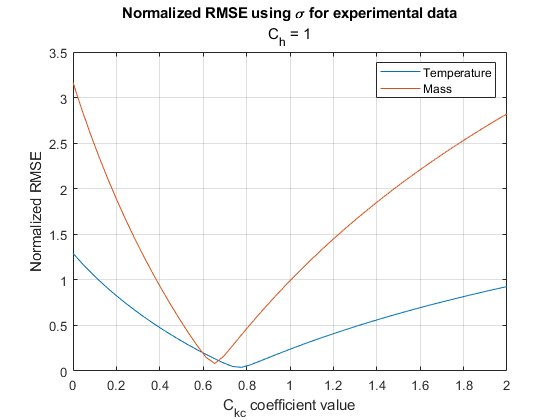

%sensativity analysis kc

h_mantel_coeff = 1;


Y_total = [];
test_parameter = linspace(0,2,50);

for i = test_parameter
kc_coeff = i;
[t,Y_test]  = ode45(@(t,Y)sysdiff(t,Y),tint,y0);

Y_total = [Y_total,Y_test];

end

residual_temp = [];
for i = linspace(1,length(Y_total(1,:))-1,length(Y_total(1,:))/2)
    residual_temp = [residual_temp, [sqrt(sum((small(2).beaker(:,2)+273.15-Y_total(:,i)).^2)/length(small(2).beaker(:,2)))/std(small(2).beaker(:,2)+273.15)]];
end

residual_mass = [];
for i = linspace(2,length(Y_total(1,:)),length(Y_total(1,:))/2)
    residual_mass = [residual_mass, [sqrt(sum((small(2).beaker(:,3)-Y_total(:,i)*1000).^2)/length(small(2).beaker(:,3))/std(small(2).beaker(:,3)))]];
end

plot(test_parameter,residual_temp,test_parameter,residual_mass)

title('Normalized RMSE using \sigma for experimental data')
subtitle('C_h = 1')
legend('Temperature', 'Mass')
xlabel('C_{kc} coefficient value')
ylabel('Normalized RMSE')
grid on

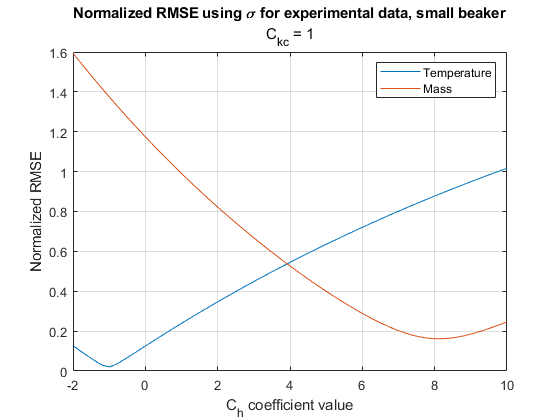

MS_norm_LOF_Temp = -0.0028

Fobs = -0.9828

Fstat = -0.6929

There is no significant lack of fit :)

Fstat = 1.3930

%sensativity analysis h_mantel

kc_coeff = 1;

Y_total = [];
test_parameter = linspace(-2,10,60);

for i = test_parameter
h_mantel_coeff = i;
[t,Y_test]  = ode45(@(t,Y)sysdiff(t,Y),tint,y0);

Y_total = [Y_total,Y_test];

end

residual_temp = [];
for i = linspace(1,length(Y_total(1,:))-1,length(Y_total(1,:))/2)
    residual_temp = [residual_temp, [sqrt(sum((small(2).beaker(:,2)+273.15-Y_total(:,i)).^2)/length(small(2).beaker(:,2)))/std(small(2).beaker(:,2)+273.15)]];
end

residual_mass = [];
for i = linspace(2,length(Y_total(1,:)),length(Y_total(1,:))/2)
    residual_mass = [residual_mass, [sqrt(sum((small(2).beaker(:,3)-Y_total(:,i)*1000).^2)/length(small(2).beaker(:,3))/std(small(2).beaker(:,3)))]];
end

plot(test_parameter,residual_temp,test_parameter,residual_mass)

title('Normalized RMSE using \sigma for experimental data, small beaker')
subtitle('C_{kc} = 1')
legend('Temperature', 'Mass')
xlabel('C_h coefficient value')
ylabel('Normalized RMSE')
grid on

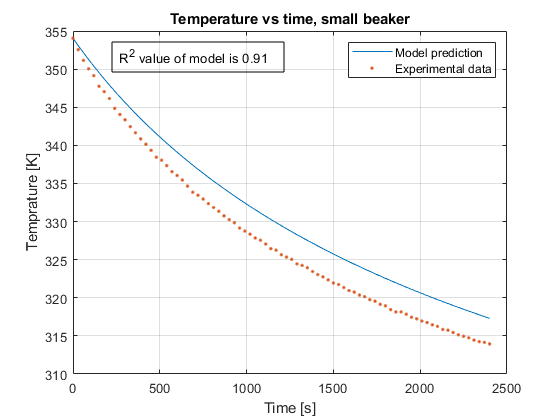

%model verification temperature data set 1

heatcontribution_top = [];
heatcontribution_mantel = [];
h_mantel_coeff = 1.736842105263158;
kc_coeff = 0.684210526315790;
y0 = [(273.15+80.9),0.18633];
tint = linspace(0,small(1).beaker(end,1),length(small(1).beaker(:,1))).*60;

[t,Y_validation]  = ode45(@(t,Y)sysdiff(t,Y),tint,y0);

SSres_temp = sum((small(1).beaker(:,2)+273.15-Y_validation(:,1)).^2);
SStot_temp = sum((small(1).beaker(:,2)+273.15-mean(small(1).beaker(:,2)+273.15)).^2);
R2 = 1 - (SSres_temp/SStot_temp);
R2string = sprintf('R^2 value of model is %.2f ',R2);

plot(t,Y_validation(:,1),small(1).beaker(:,1)*60,small(1).beaker(:,2)+273.15,'.')

dim = [.2 .6 .3 .3];
annotation('textbox',dim,'String',R2string,'FitBoxToText','on');

title('Temperature vs time, small beaker')
legend('Model prediction','Experimental data')
xlabel('Time [s]')
ylabel('Temprature [K]')
grid on

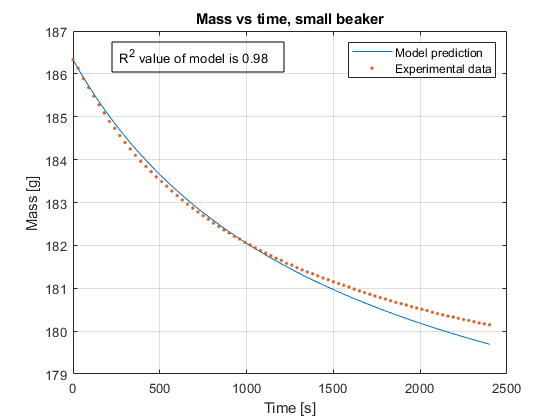

%model verification mass data set 1

heatcontribution_top = [];
heatcontribution_mantel = [];
h_mantel_coeff = 1.736842105263158;
kc_coeff = 0.684210526315790;
y0 = [(273.15+80.9),0.18633];
tint = linspace(0,small(1).beaker(end,1),length(small(1).beaker(:,3))).*60;

[t,Y_validation]  = ode45(@(t,Y)sysdiff(t,Y),tint,y0);

SSres_mass = sum((small(1).beaker(:,3)-Y_validation(:,2)*1000).^2);
SStot_mass = sum((small(1).beaker(:,3)-mean(small(1).beaker(:,3))).^2);
R2 = 1 - (SSres_mass/SStot_mass);

R2string = sprintf('R^2 value of model is %.2f ',R2);


plot(t,Y_validation(:,2)*1000,small(1).beaker(:,1)*60,small(1).beaker(:,3),'.')

dim = [.2 .6 .3 .3];
annotation('textbox',dim,'String',R2string,'FitBoxToText','on');

title('Mass vs time, small beaker')
legend('Model prediction','Experimental data')
xlabel('Time [s]')
ylabel('Mass [g]')
grid on

%Cup design test

heatcontribution_top = [];
heatcontribution_mantel = [];
h_mantel_coeff = 1.736842105263158;
kc_coeff = 0.684210526315790;
y0 = [(273.15+80.9),0.18633];
L_glass = 5e-3;
k_glass = glass.heat_conduction % aerogel: 0,003 w/mk

k_glass = 0.9000


tint = linspace(0,2000*60,2001);

[t,Y_coffedesign]  = ode45(@(t,Y)sysdiff_cupdesign(t,Y),tint,y0);


[t/60,Y_coffedesign(:,1)-273.15]

ans = 	1.0e+03 *

         0    0.0809
    0.0010    0.0808
    0.0020    0.0806
    0.0030    0.0805
    0.0040    0.0803
    0.0050    0.0802
    0.0060    0.0801
    0.0070    0.0799
    0.0080    0.0798
    0.0090    0.0797
